root_directory = 'data';
file = '/SAW_without_skin_0deg_pos.txt'

file = '/SAW_without_skin_0deg_pos.txt'


data = importdata([root_directory file]);
t_0deg_without(:) = data.data(:,1);
x_0deg_without(:) = data.data(:,2);
reg_0deg_without = line_regress(t_0deg_without,x_0deg_without,1);

file = '/SAW_without_skin_5deg_pos.txt'

file = '/SAW_without_skin_5deg_pos.txt'


data = importdata([root_directory file]);
t_5deg_without(:) = data.data(:,1);
x_5deg_without(:) = data.data(:,2);
reg_5deg_without = line_regress(t_5deg_without,x_5deg_without,1);

file = '/SAW_without_skin_10deg_pos.txt'

file = '/SAW_without_skin_10deg_pos.txt'

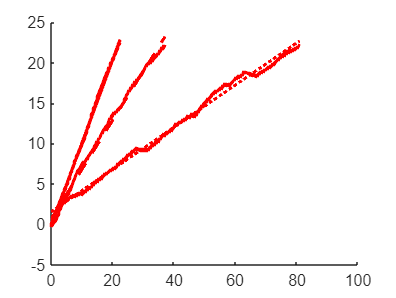

data = importdata([root_directory file]);
t_10deg_without(:) = data.data(:,1);
x_10deg_without(:) = data.data(:,2);
reg_10deg_without = line_regress(t_10deg_without,x_10deg_without,1);

f = figure();
hold on
plot(t_0deg_without,x_0deg_without,'rx','MarkerSize',1.5)
plot(t_0deg_without,reg_0deg_without.yfit,'r','linewidth',2)
plot(t_5deg_without,x_5deg_without,'rx','markersize',1.5)
plot(t_5deg_without,reg_5deg_without.yfit,'r--','linewidth',2)
plot(t_10deg_without,x_10deg_without,'rx','markersize',1.5)
plot(t_10deg_without,reg_10deg_without.yfit,'r:','linewidth',2)

file = '/SAW_with_skin_0deg_pos.txt'

file = '/SAW_with_skin_0deg_pos.txt'


data = importdata([root_directory file]);
t_0deg(:) = data.data(:,1);
x_0deg(:) = data.data(:,2);
reg_0deg = line_regress(t_0deg,x_0deg,1);

file = '/SAW_with_skin_5deg_pos.txt'

file = '/SAW_with_skin_5deg_pos.txt'


data = importdata([root_directory file]);
t_5deg(:) = data.data(:,1);
x_5deg(:) = data.data(:,2);
reg_5deg = line_regress(t_5deg,x_5deg,1);

file = '/SAW_with_skin_10deg_pos.txt'

file = '/SAW_with_skin_10deg_pos.txt'

data = importdata([root_directory file]);
t_10deg(:) = data.data(:,1);
x_10deg(:) = data.data(:,2);
reg_10deg = line_regress(t_10deg,x_10deg,1);

figure(f);
hold on
plot(t_0deg,x_0deg,'bx','MarkerSize',1.5)
plot(t_0deg,reg_0deg.yfit,'b','linewidth',2)
plot(t_5deg,x_5deg,'bx','markersize',1.5)
plot(t_5deg,reg_5deg.yfit,'b--','linewidth',2)
plot(t_10deg,x_10deg,'bx','markersize',1.5)
plot(t_10deg,reg_10deg.yfit,'b:','linewidth',2)

x0=10;
y0=10;
width=550;
height=450;
set(gcf,'position',[x0,y0,width,height]);
yticks([0:12.5:25])
xticks([0:20:80])
ylim([0 25])
xlim([0 84])
ylabel("Displacement [cm]","Interpreter","latex")
xlabel('Time [s]','interpreter','latex')
title('Propulsion','interpreter','latex')
lgnd= legend('Without skin','Flat','','$5^{\circ}$ incline','','$10^{\circ}$ incline','With skin','Flat','','$5^{\circ}$ incline','','$10^{\circ}$ incline','Interpreter','latex','location','southeast')

lgnd =   Legend (Without skin, Flat, $5^{\circ}$ incline, $10^{\circ}$ incline, With skin, Flat, $5^{\circ}$ incline, $10^{\circ}$ incline) with properties:

         String: {'Without skin'  'Flat'  '$5^{\circ}$ incline'  '$10^{\circ}$ incline'  'With skin'  'Flat'  '$5^{\circ}$ incline'  '$10^{\circ}$ incline'}
       Location: 'southeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6674 0.1338 0.2188 0.2724]
          Units: 'normalized'

  Show all properties


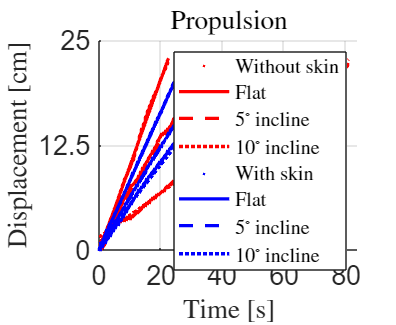

fontsize(16,'points')
fontsize(lgnd,12,'points')
grid on